l_0 = 0.5; 
muscle = FittedMuscleMechanics(l_0);
bellow = FittedBellowMechanics(l_0);

res = 20;

% Compute force surface of the muscle
e_muscle = linspace(muscle.e_bounds(1), muscle.e_bounds(2), res);
p_muscle = linspace(muscle.a_bounds(1), muscle.a_bounds(2), res);
[E_muscle, P_muscle] = meshgrid(e_muscle, p_muscle);

F_muscle = zeros(res, res);
for i = 1 : res
    for j = 1 : res
        strain_i = E_muscle(i,j);
        actuation_i = P_muscle(i, j);
        F_muscle(i, j) = muscle.f_force(strain_i, actuation_i);
    end
end
free_contraction_muscle = contourc(e_muscle, p_muscle, F_muscle, [0,0]);
free_contraction_muscle = free_contraction_muscle(:, 2:end);

% Compute force surface of the bellow
e_bellow= linspace(bellow.e_bounds(1), bellow.e_bounds(2), res);
p_bellow = linspace(bellow.a_bounds(1), bellow.a_bounds(2), res);
[E_bellow, P_bellow] = meshgrid(e_bellow, p_bellow);

F_bellow= zeros(res, res);
for i = 1 : res
    for j = 1 : res
        strain_i = E_bellow(i,j);
        actuation_i = P_bellow(i, j);
        F_bellow(i, j) = bellow.f_force(strain_i, actuation_i);
    end
end
free_contraction_bellow = contourc(e_bellow, p_bellow, F_bellow, [0,0]);
free_contraction_bellow= free_contraction_bellow(:, 2:end);

color_green = [45 182 125] / 255;
color_yellow = [255 176 0] / 255;
color_blue = [100 143 255] / 255;
color_red = [255 48 150] / 255;
colors = [color_red; color_blue; color_yellow];

% Lighter colors
color_light_green = [130 205 174] / 255;
color_light_yellow = [248 203 97] / 255;
color_light_blue = [135 167 250] / 255;
color_light_red = [230 100 164] / 255;
colors_light = [color_light_red; color_light_blue; color_light_yellow];

% Darker colors
color_dark_green = [0.0706    0.5137    0.3294];
color_dark_blue = [0.2941    0.4196    0.7490];
color_dark_yellow = [0.7490    0.5176         0];
color_dark_red = [0.6549    0.1059    0.3725];
colors_dark = [color_dark_red; color_dark_blue; color_dark_yellow];

fig = figure("visible", true, "Position", [50, 300, 1000, 400]);
cmap_binary = [
    color_blue;
    color_red;
];
cmap_binary_dark = [
    color_dark_blue;
    color_dark_red;
];

ax = subplot(1, 2, 1)

ax =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.3347 0.8150]
            Units: 'normalized'

  Show all properties


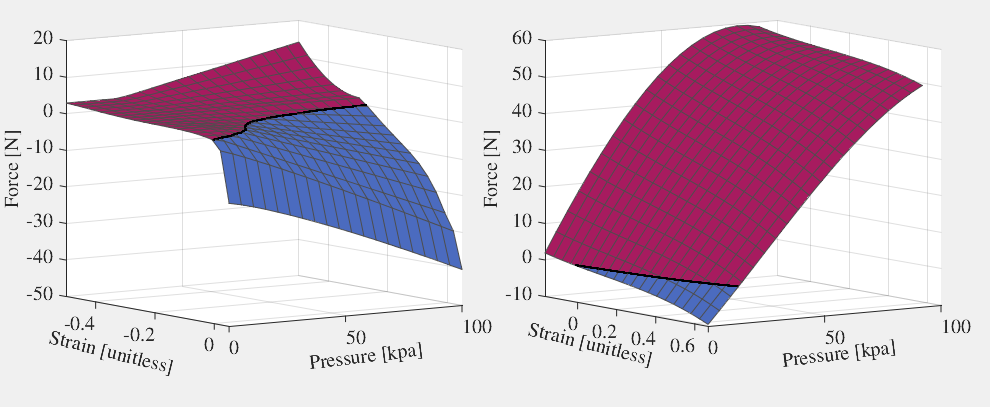

hold on
%mesh(E_muscle, P_muscle, F_muscle, "facecolor", color_light_red, "edgecolor", color_dark_red, "linewidth", 1.2);
surf(E_muscle, P_muscle, F_muscle, "linewidth", 0.1, "edgecolor", [0.3 0.3 0.3], "facecolor", "interp");
plot3(free_contraction_muscle(1, :), free_contraction_muscle(2, :), zeros(length(free_contraction_muscle)) + 0.1, "k", "linewidth", 1);
xlabel("Strain [unitless]", "rotation", -14, "Position", [-0.140741701316817,1.530846462551417,-61.958948074023965]);
ylabel("Pressure [kpa]", "rotation", 7, "Position", [0.017500855794101,37.92236625112355,-60.39549236950609]);
zlabel("Force [N]")
grid on
view([55, 8]);
set(gca, "Position", [0.0665, 0.2, 0.40, 0.75])
colormap(cmap_binary_dark)
clim([-1, 1])

subplot(1, 2, 2);
hold on
surf(E_bellow, P_bellow, F_bellow, "linewidth", 0.1, "edgecolor", [0.3, 0.3, 0.3], "facecolor", "interp");
plot3(free_contraction_bellow(1, :), free_contraction_bellow(2, :), zeros(length(free_contraction_bellow)) + 0.1, "k", "linewidth", 1);
xlabel("Strain [unitless]", "rotation", -14, "Position", [0.313222510633526,6.910200181778691,-20.640589365986955]);
ylabel("Pressure [kpa]", "rotation", 7, "Position", [0.607859921328192,36.26080309167901,-19.68307625442162]);
zlabel("Force [N]")
grid on
view([55, 8]);
fontname("Nimbus Roman")
fontsize(15, "points")
set(gca, "Position", [0.55, 0.2, 0.40, 0.75])
colormap(cmap_binary_dark)
clim([-1, 1])

%set(gca,"PositionConstraint", "outerposition")

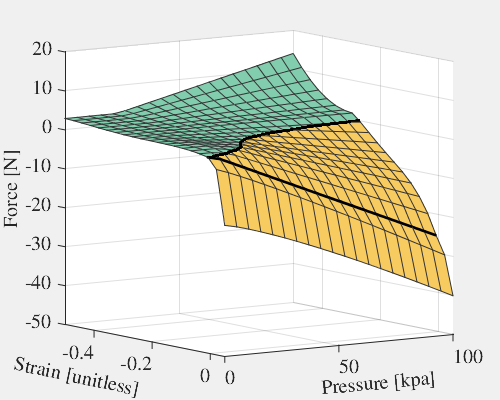

figure("Visible", true, "Position", [0, 0, 500, 400])
hold on
% Plot the force surface
surf(E_muscle, P_muscle, F_muscle, "linewidth", 0.3, "edgecolor", [0.2 0.2 0.2], "facecolor", "interp");

% Plot the free contraction line
plot3(free_contraction_muscle(1, :), free_contraction_muscle(2, :), zeros(length(free_contraction_muscle)) + 0.1, "k", "linewidth", 1.5);

% Plot the division between actuation and passive extension
[~, i_min] = min(abs(E_muscle(1, :)));
plot3(E_muscle(:, i_min), P_muscle(:, i_min), F_muscle(:, i_min) + 0.01, "k", "linewidth", 2)
xlabel("Strain [unitless]", "rotation", -12, "position", [-0.219729273319025,-2.247470357670863,-60.330599846703535]);
ylabel("Pressure [kpa]", "rotation", 5, "Position", [-0.017535021699697,50.44849578109779,-59.77767147982996]);
zlabel("Force [N]")
grid on
view([55, 8]);
fontname("Nimbus Roman")
fontsize(15, "points")
cmap_binary_light = [
    color_light_yellow;
    color_light_green
];
colormap(cmap_binary_light)
clim([-1, 1])

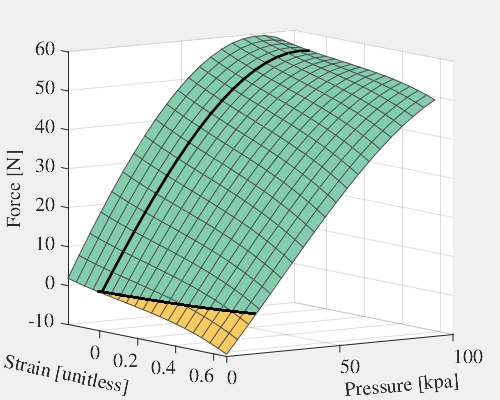

figure("Visible", true, "Position", [0, 0, 500, 400])
hold on
% Plot the force surface
surf(E_bellow, P_bellow, F_bellow, "linewidth", 0.3, "edgecolor", [0.3 0.3 0.3], "facecolor", "interp");

% Plot the free contraction line
plot3(free_contraction_bellow(1, :), free_contraction_bellow(2, :), zeros(length(free_contraction_bellow)) + 0.1, "k", "linewidth", 1.5);

% Plot the division between actuation and passive compression
[~, i_min] = min(abs(E_bellow(1, :)));
plot3(E_bellow(:, i_min), P_bellow(:, i_min), F_bellow(:, i_min) + 0.01, "k", "linewidth", 2)

xlabel("Strain [unitless]", "rotation", -12);
ylabel("Pressure [kpa]", "rotation", 5);
zlabel("Force [N]")
grid on
view([55, 8]);
fontname("Nimbus Roman")
fontsize(15, "points")
colormap(cmap_binary_light)
clim([-1, 1])